# Examen sistemas dinámicos y Realimentación. Noviembre 2023

Construimos las matrices del sistema.

clear all
close all
kv = 1 %valvula abierta

kv = 1

Ao = [-3 1 1 1; 1 -2 0 1;1 0 -2 1;1 1 1 -3-kv]

Ao =     -3     1     1     1
     1    -2     0     1
     1     0    -2     1
     1     1     1    -4


kv = 0 %valvula cerrada

kv = 0

Ac = [-3 1 1 1; 1 -2 0 1;1 0 -2 1;1 1 1 -3-kv]

Ac =     -3     1     1     1
     1    -2     0     1
     1     0    -2     1
     1     1     1    -3


B = [1 -1 -1 -1; 0 1 0 0; 0 0 1 0;0 0 0 1]

B =      1    -1    -1    -1
     0     1     0     0
     0     0     1     0
     0     0     0     1


C = [1 0 0 0;0 0 1 0;0 0 0 1]

C =      1     0     0     0
     0     0     1     0
     0     0     0     1


%C = [0 0 0 1;0 0 1 0]
%C = [1 0 0 0; 0 0 0 1]

Comprobamos la estabilidad de la matriz A para Kv = 1 (valvula abierta)

[Vo,Lo] = eig(Ao)

Vo =    -0.2399   -0.8165   -0.0000    0.5251
   -0.2399    0.4082   -0.7071    0.5251
   -0.2399    0.4082    0.7071    0.5251
    0.9096         0         0    0.4155


Lo =    -4.7913         0         0         0
         0   -4.0000         0         0
         0         0   -2.0000         0
         0         0         0   -0.2087


El sistema es estable, o dicho de otra manera, si no hay oporte en la entrada del depósito 1, el sistema termina por vaciarse con la valvula abierta.

Comprobamos la estabilidad para Kv = 0 (valvula cerrada) 

[Vc,Lc] = eig(Ac)

Vc =    -0.8165   -0.2887   -0.0000    0.5000
    0.4082   -0.2887   -0.7071    0.5000
    0.4082   -0.2887    0.7071    0.5000
         0    0.8660         0    0.5000


Lc =    -4.0000         0         0         0
         0   -4.0000         0         0
         0         0   -2.0000         0
         0         0         0   -0.0000


En este segundo caso, tenemos un autovalor cero y el resto negativo. El autovector correspondiente tiene todos sus elementos iguales, lo que corresponde al hecho esperable de que el sistema tiende a equilibrar el nivel en todos los depósitos.

El sistema es controlable.

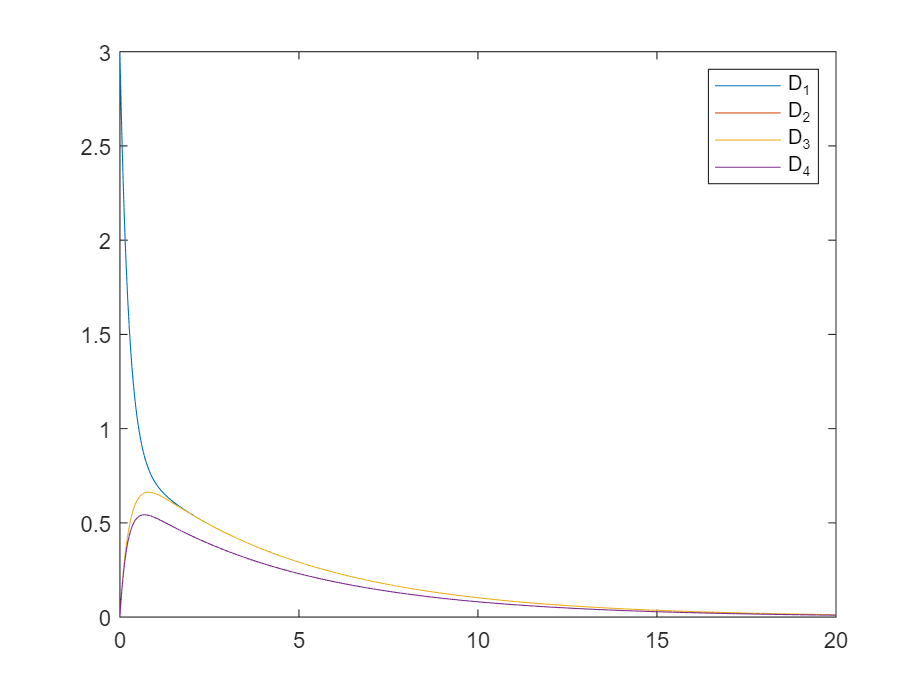

sys = @(t,x)sistema_lineal(t,x,Ao);
tf = 20;
x0 = [3;0;0;0]; %elegimos unas c iniciales en rango pedido
[t,x] = ode45(sys,[0,tf],x0);
figure(1)
plot(t,x)
legend('D_1','D_2','D_3','D_4')

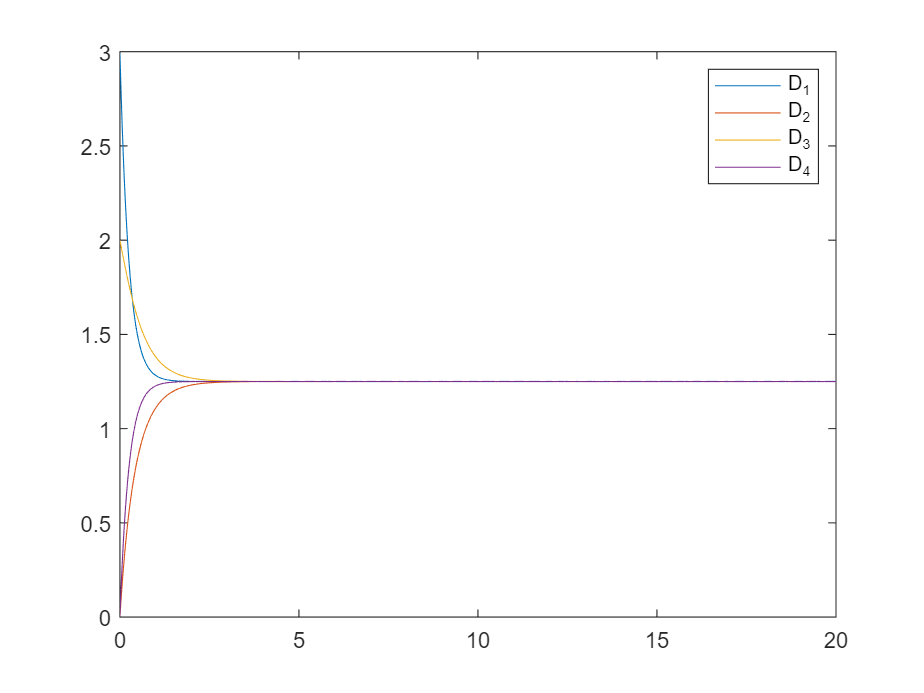


sys = @(t,x)sistema_lineal(t,x,Ac);
tf = 20;
x0 = [3;0;2;0]; %elegimos unas c iniciales en rango pedido
[t,x] = ode45(sys,[0,tf],x0);
figure(1)
plot(t,x)
legend('D_1','D_2','D_3','D_4')

Analizamos a continuación el sistema para válvula abierta:

Empezamos por analizar su controlabilidad y observabilidad:

%controlabilidad matriz de controlabilidad
rank(ctrb(Ao,B))

ans = 4

rank(ctrb(Ac,B)) %podríamos vaciar los tanques con la bomba de entrada.

ans = 4

%test de autovalores
[Vot,Lot] = eig(Ao')

Vot =    -0.2399   -0.8165   -0.0000    0.5251
   -0.2399    0.4082   -0.7071    0.5251
   -0.2399    0.4082    0.7071    0.5251
    0.9096         0         0    0.4155


Lot =    -4.7913         0         0         0
         0   -4.0000         0         0
         0         0   -2.0000         0
         0         0         0   -0.2087



B'*Vot

ans =    -0.2399   -0.8165   -0.0000    0.5251
         0    1.2247   -0.7071         0
         0    1.2247    0.7071   -0.0000
    1.1495    0.8165    0.0000   -0.1096


[Vct,Lct] = eig(Ac')

Vct =    -0.8165   -0.2887   -0.0000    0.5000
    0.4082   -0.2887   -0.7071    0.5000
    0.4082   -0.2887    0.7071    0.5000
         0    0.8660         0    0.5000


Lct =    -4.0000         0         0         0
         0   -4.0000         0         0
         0         0   -2.0000         0
         0         0         0   -0.0000


B'*Vct

ans =    -0.8165   -0.2887   -0.0000    0.5000
    1.2247         0   -0.7071         0
    1.2247         0    0.7071   -0.0000
    0.8165    1.1547    0.0000   -0.0000



%observabilidad
rank(obsv(Ao,C))

ans = 4

rank(obsv(Ac,C))

ans = 4

%test de autovalores
C*Vo

ans =    -0.2399   -0.8165   -0.0000    0.5251
   -0.2399    0.4082    0.7071    0.5251
    0.9096         0         0    0.4155


C*Vc

ans =    -0.8165   -0.2887   -0.0000    0.5000
    0.4082   -0.2887    0.7071    0.5000
         0    0.8660         0    0.5000


mu = 5 %mayor que el menor autovalor de A en valor absoluto  

mu = 5

W = lyap(-mu*eye(4)-Ao,B*B')

W =     2.1000   -0.4000   -0.4000   -1.4000
   -0.4000    0.4333    0.2667   -0.4000
   -0.4000    0.2667    0.4333   -0.4000
   -1.4000   -0.4000   -0.4000    2.7000


eig(W) %comprobamos que la solucion es definida positiva

ans =     0.0262
    0.1667
    1.6395
    3.8342


P = W^-1

P =     9.5152    9.9394    9.9394    7.8788
    9.9394   14.2424    8.2424    8.4848
    9.9394    8.2424   14.2424    8.4848
    7.8788    8.4848    8.4848    6.9697


K = B'*P/2

K =     4.7576    4.9697    4.9697    3.9394
    0.2121    2.1515   -0.8485    0.3030
    0.2121   -0.8485    2.1515    0.3030
   -0.8182   -0.7273   -0.7273   -0.4545


eig(Ao-B*K)

ans =   -5.0000 + 0.7385i
  -5.0000 - 0.7385i
  -5.0000 + 0.0000i
  -5.0000 + 0.0000i


Colocamos ahora unos polos para el observador

L = place(Ao',C',[-12,-13,-14,-15])'

L =    16.9784    1.0000    7.0212
   72.2389         0   72.7611
    1.0000   10.0000    1.0000
    6.9788    1.0000   16.0216


eig(Ao-L*C)

ans =   -13.0000
  -15.0000
  -14.0000
  -12.0000


Y construimos la matriz ampliada con todo


Amp = [Ao -B*K; L*C Ao-B*K-L*C]

Amp =    -3.0000    1.0000    1.0000    1.0000   -5.1515   -4.3939   -4.3939   -3.7879
    1.0000   -2.0000         0    1.0000   -0.2121   -2.1515    0.8485   -0.3030
    1.0000         0   -2.0000    1.0000   -0.2121    0.8485   -2.1515   -0.3030
    1.0000    1.0000    1.0000   -4.0000    0.8182    0.7273    0.7273    0.4545
   16.9784         0    1.0000    7.0212  -25.1299   -3.3939   -4.3939   -9.8091
   72.2389         0         0   72.7611  -71.4510   -4.1515    0.8485  -72.0642
    1.0000         0   10.0000    1.0000   -0.2121    0.8485  -14.1515   -0.3030
    6.9788         0    1.0000   16.0216   -5.1606    1.7273    0.7273  -19.5671


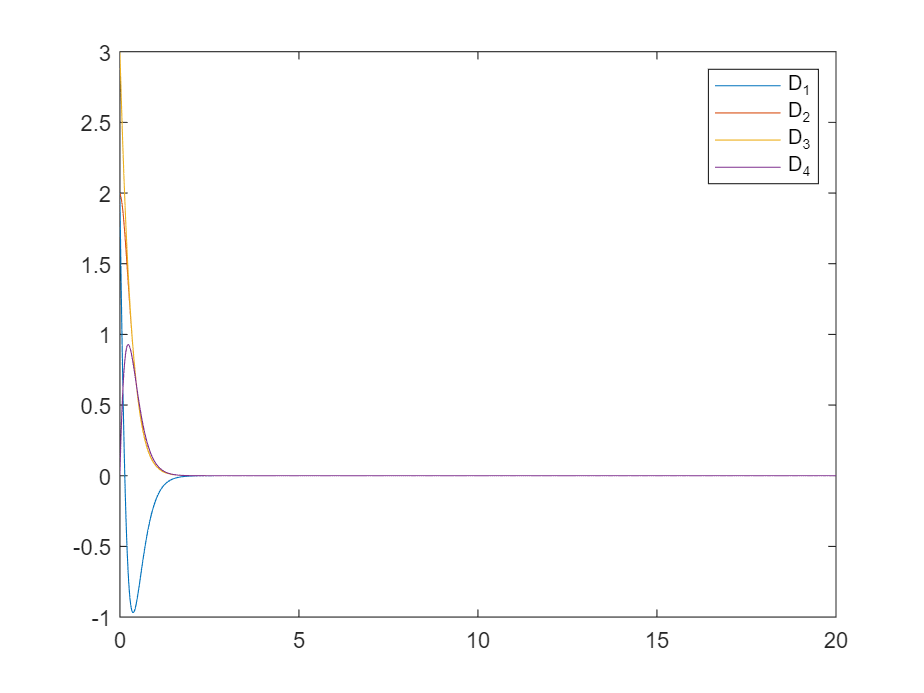

sys = @(t,x)sistema_lineal(t,x,Amp);
tf = 20;
x0 = [2;2;3;0;2;0;2;0]; %elegimos unas c 
[t,x] = ode45(sys,[0,tf],x0);
figure(2)
subplot
plot(t,x(:,1:4))
legend('D_1','D_2','D_3','D_4')

La pega evidente es que los depósitos con valores complejos queden exhaustos y obtendremos valores negativos para el nivel en el transitorio. Recalculamos una ganacia con place y repetimos

K = place(Ao,B,[-1,-2,-3,-4]) %polos rápidos

K =     1.0000    2.0000    3.0000    3.0000
    1.0000    0.0000    0.0000    1.0000
    1.0000    0.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    0.0000


%K = place(Ao,B,[-0.2,-0.1,-0.15,-0.05]) %polos lentos
Amp = [Ao -B*K; L*C Ao-B*K-L*C]

Amp =    -3.0000    1.0000    1.0000    1.0000    2.0000   -1.0000   -1.0000   -1.0000
    1.0000   -2.0000         0    1.0000   -1.0000   -0.0000   -0.0000   -1.0000
    1.0000         0   -2.0000    1.0000   -1.0000   -0.0000   -1.0000   -1.0000
    1.0000    1.0000    1.0000   -4.0000   -1.0000   -1.0000   -1.0000   -0.0000
   16.9784         0    1.0000    7.0212  -17.9784    0.0000   -1.0000   -7.0212
   72.2389         0         0   72.7611  -72.2389   -2.0000   -0.0000  -72.7611
    1.0000         0   10.0000    1.0000   -1.0000   -0.0000  -13.0000   -1.0000
    6.9788         0    1.0000   16.0216   -6.9788   -0.0000   -1.0000  -20.0216


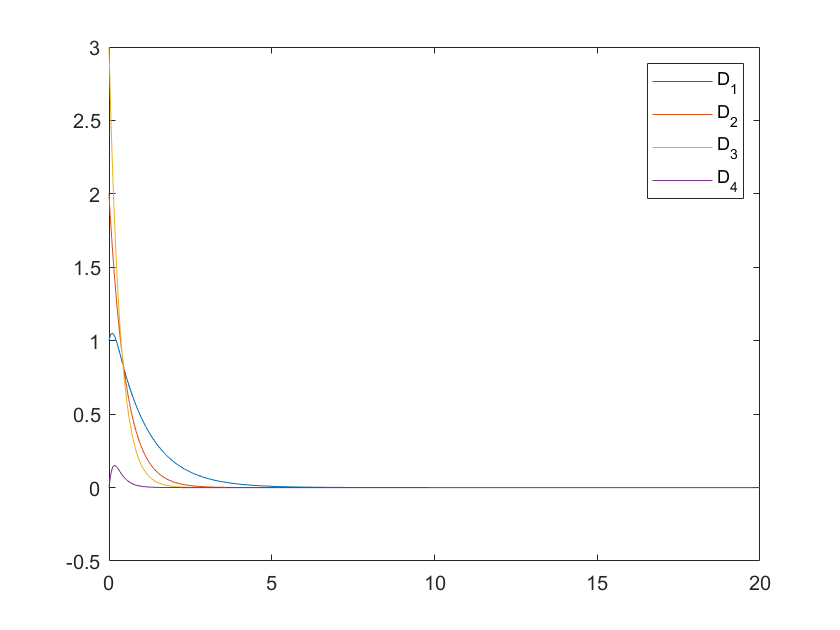

sys = @(t,x)sistema_lineal(t,x,Amp);
tf = 20;
x0 = [1;2;3;0;1;0;3;0]; %elegimos unas c 
[t,x] = ode45(sys,[0,tf],x0);
figure(1)
plot(t,x(:,1:4))
legend('D_1','D_2','D_3','D_4')

figure(2)

u = K*x(:,1:4)'

u =    14.0000   13.9993   13.9986   13.9979   13.9972   13.9937   13.9902   13.9866   13.9831   13.9656   13.9481   13.9306   13.9132   13.8378   13.7630   13.6887   13.6148   13.4875   13.3615   13.2364   13.1123   12.9411   12.7714   12.6030   12.4358   12.2253   12.0164   11.8093   11.6040   11.3558   11.1103   10.8677   10.6279   10.3443   10.0653    9.7912    9.5223    9.2063    8.8983    8.5985    8.3071    7.9608    7.6273    7.3068    6.9989    6.5987    6.2211    5.8655    5.5309    5.1750
    1.0000    1.0001    1.0002    1.0002    1.0003    1.0007    1.0011    1.0014    1.0018    1.0037    1.0055    1.0074    1.0093    1.0172    1.0250    1.0327    1.0402    1.0528    1.0648    1.0763    1.0873    1.1016    1.1147    1.1267    1.1376    1.1497    1.1602    1.1689    1.1761    1.1827    1.1872    1.1898    1.1906    1.1893    1.1860    1.1808    1.1739    1.1639    1.1522    1.1392    1.1250    1.1064    1.0868    1.0666    1.0460    1.0176    0.9892    0.9610    0.9334    0

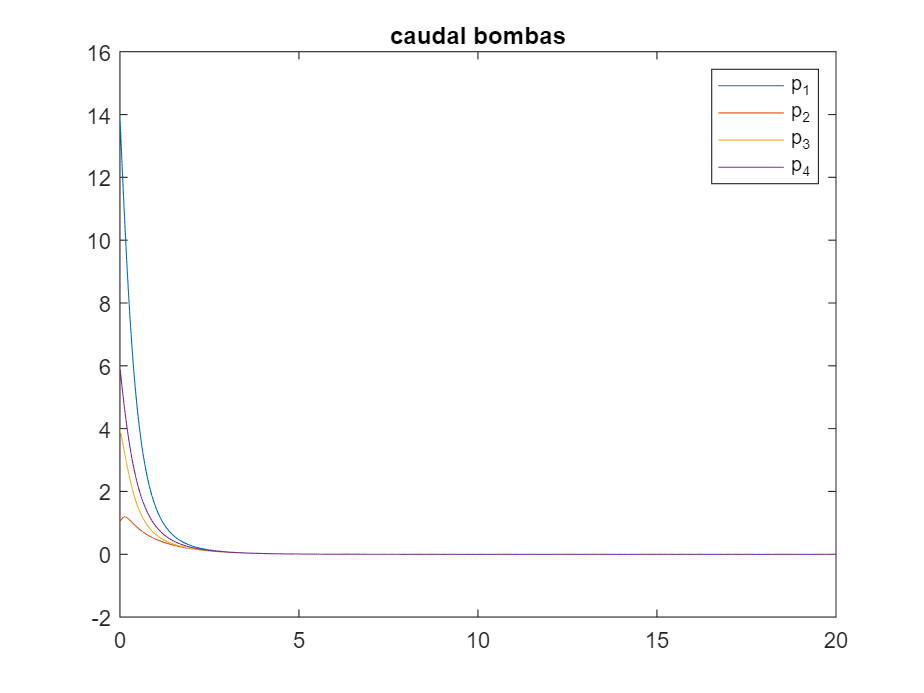

plot(t,u')
title('caudal bombas')
legend('p_1','p_2','p_3','p_4')

Añadimos control integral para controlar la altura de los depósitos

C2 = eye(4)

C2 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


Aoa = [Ao zeros(4,size(C2,1)); C2 zeros(size(C2,1))] %ampliada para incluir la altura del último depo

Aoa =     -3     1     1     1     0     0     0     0
     1    -2     0     1     0     0     0     0
     1     0    -2     1     0     0     0     0
     1     1     1    -4     0     0     0     0
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0


Ba = [B;zeros(4,4)]

Ba =      1    -1    -1    -1
     0     1     0     0
     0     0     1     0
     0     0     0     1
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


rank(ctrb(Aoa,Ba)) %controlable, tira que te va

ans = 8

%calculamos la K
K = place(Aoa,Ba, [-5,-3,-4,-4.5,-1,-2,-3.5,-2.5])

K =     6.0000    8.5000    5.0000    5.0000    8.7500   18.0000    6.0000    5.0000
    1.0000    6.5000    0.0000    1.0000    0.0000   18.0000    0.0000    0.0000
    1.0000    0.0000    3.0000    1.0000    0.0000    0.0000    6.0000    0.0000
    1.0000    1.0000    1.0000    2.0000    0.0000    0.0000    0.0000    5.0000


Construimos la matriz completa con realimentacion de estados estimados y control integral

h4 =[1;2;3;4]; %consigna para los tanques
%AoI = [Ao -B*K(:,1:4) -B*K(:,5:end); L*C Ao-B*K(:,1:4)-L*C -B*K(:,5:end); C2 zeros(size(C2) zeros(size(C2)) ]
%Como no se tiene acceso a todos los estados, lo correcto sería obtener los
%valores de las salidas a partir de los estados estimados, para aplicar el
%control integral. Esto se cosigue fácilmente itercambiando la posicion de
%la matriz C2 con la matriz de ceros zeros(size(C2) que la sigue en la
%ecuación de más arriba.
AoI = [Ao -B*K(:,1:4) -B*K(:,5:end); L*C Ao-B*K(:,1:4)-L*C -B*K(:,5:end); zeros(size(C2)) C2 zeros(size(C2)) ]

AoI =    -3.0000    1.0000    1.0000    1.0000   -3.0000   -1.0000   -1.0000   -1.0000   -8.7500   -0.0000   -0.0000         0
    1.0000   -2.0000         0    1.0000   -1.0000   -6.5000   -0.0000   -1.0000   -0.0000  -18.0000   -0.0000   -0.0000
    1.0000         0   -2.0000    1.0000   -1.0000   -0.0000   -3.0000   -1.0000   -0.0000   -0.0000   -6.0000   -0.0000
    1.0000    1.0000    1.0000   -4.0000   -1.0000   -1.0000   -1.0000   -2.0000   -0.0000   -0.0000   -0.0000   -5.0000
   16.9784         0    1.0000    7.0212  -22.9784   -0.0000   -1.0000   -7.0212   -8.7500   -0.0000   -0.0000         0
   72.2389         0         0   72.7611  -72.2389   -8.5000   -0.0000  -72.7611   -0.0000  -18.0000   -0.0000   -0.0000
    1.0000         0   10.0000    1.0000   -1.0000   -0.0000  -15.0000   -1.0000   -0.0000   -0.0000   -6.0000   -0.0000
    6.9788         0    1.0000   16.0216   -6.9788   -0.0000   -1.0000  -22.0216   -0.0000   -0.0000   -0.0000   -5.0000
         0         0      

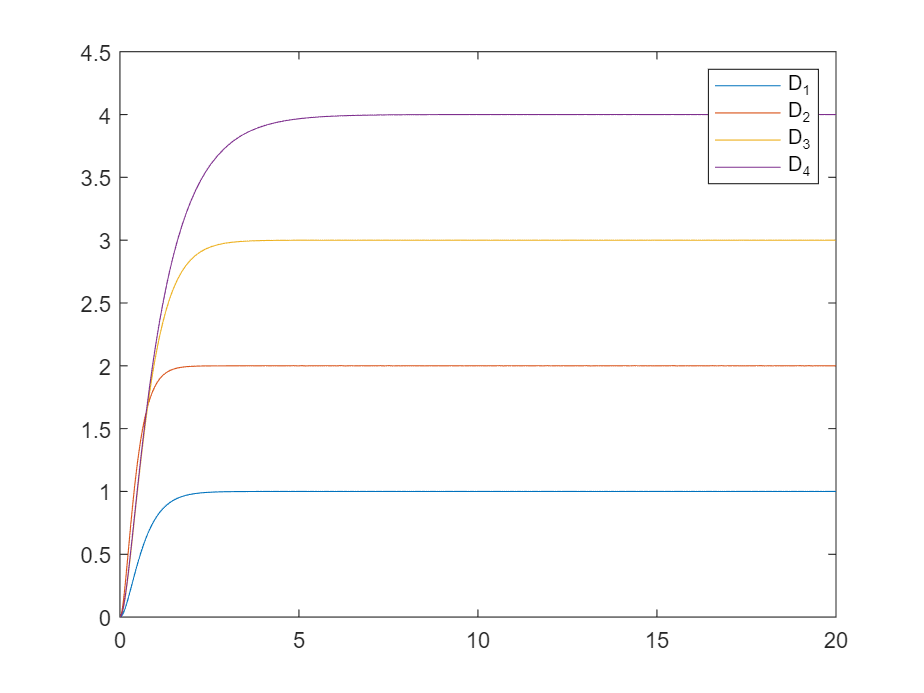


x0 = [0;0;0;0;0;0;0;0;0;0;0;0]; %elegimos unas condiciones iniciales
sys = @(t,x)sistema_lineal_I(t,x,h4,AoI);
[t,x] = ode45(sys,[0,tf],x0);
figure(1)
plot(t,x(:,1:4))
legend('D_1','D_2','D_3','D_4')

Estudiamos las posibilidades de observar el sistema con solo dos sensores

C12 = [1 0 0 0; 0 1 0 0] %en depos 1 y 2

C12 =      1     0     0     0
     0     1     0     0


rank(obsv(Ao,C12))

ans = 4

C14 = [1 0 0 0;0 0 0 1]

C14 =      1     0     0     0
     0     0     0     1


rank(obsv(Ao,C14))

ans = 3

C23 = [0 1 0 0; 0 0 1 0]

C23 =      0     1     0     0
     0     0     1     0


rank(obsv(Ao,C23))

ans = 4

C24 = [0 1 0 0; 0 0 0 1]

C24 =      0     1     0     0
     0     0     0     1


rank(obsv(Ao,C24))

ans = 4

function xdot = sistema_lineal(t,x,A)
%Modelo lineal elemental para estudiar la evolucion
%desde un valor inicial
xdot = A*x;
end

function xdot = sistema_lineal_I(t,x,yd,A)
%modificamos el sistema lineal para ponerlo en modo realimentación
%Debemos añadir la entrada al error, que corresponde a yd
xdot = A*x+[zeros(size(x,1)-length(yd),1);-yd];
end

